# Plot Channel RSW adjustment solution.

See `RSW_adjustment_movie.key` for animations.

cd to working directory to run from the command line.

twnh Jun '21

## Initialise

fprintf(1,' Initialize...') ;

 Initialize...

tic
close all
clear
more off
params = define_params ;

 Channel length      = [32.0],
 Channel width       = [2.00],
 Deformation radius  = [0.50],
 Gravity wave speed  = [0.50],

 Grid resolution     = [1024 x  64 x 256] [NX x NY x NT],
 Number of particles = [  64],
 Delta_eta           = [0.020],


## Compute Eulerian solution

fprintf(1,'\n Compute solution...\n') ;


 Compute solution...


tic
eta_KW  = zeros(numel(params.x),numel(params.y),numel(params.ts)) ;
eta_IGW = zeros(numel(params.x),numel(params.y),numel(params.ts)) ;
u_KW    = zeros(numel(params.x),numel(params.y),numel(params.ts)) ;
u_IGW   = zeros(numel(params.x),numel(params.y),numel(params.ts)) ;
v_IGW   = zeros(numel(params.x),numel(params.y),numel(params.ts)) ;
fprintf('  Step: ')

  Step: 

for tt = 1:numel(params.ts)
    fprintf('%4.0d ',tt)
    [tmp_KW, tmp_IGW, tmp_uKW, tmp_uIGW] = compute_eta_u(params.ts(tt),params) ;
    eta_KW( :,:,tt)  = tmp_KW ;
    eta_IGW(:,:,tt)  = tmp_IGW ;
    u_KW(   :,:,tt)  = tmp_uKW ;
    u_IGW(  :,:,tt)  = tmp_uIGW ;
    v_IGW(  :,:,tt)  = compute_v(params.ts(tt),params) ;
    fprintf('\b\b\b\b\b')
end

   1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37 

etaH = struct('total',eta_KW + eta_IGW,'KW',eta_KW,'IGW',eta_IGW) ;
uH   = struct('total',  u_KW +   u_IGW,'KW',  u_KW,'IGW',  u_IGW) ;
vH   = struct('total',           v_IGW,            'IGW',  v_IGW) ;
fprintf(1,'%4.0d.\n   Done in [%6.3f]s.\n',tt,toc) ;

## Compute Lagrangian trajectories

fprintf(1,' Solve Lagrangian trajectories...') ;
tic
rng('default')
s = rng ;
part_x_0         = (params.channel_length/3).*(rand(params.Np,1)-0.5) ;      % Start them near the origin
part_x_0         = [part_x_0; params.M.*(rand(params.Np,1)-0.5)] ;
[xmat,ymat,tmat] = ndgrid(params.x,params.y,params.ts) ;
uInterp          = griddedInterpolant(xmat,ymat,tmat,params.Delta_eta.*uH.total) ;
vInterp          = griddedInterpolant(xmat,ymat,tmat,params.Delta_eta.*vH.total) ;
[t,part_x]       = ode45(@(t,part_x)rhs_particle(t,part_x,uInterp,vInterp),params.ts,part_x_0) ;
fprintf(1,'done in [%6.3f]s.\n',toc) ;

## Plot animation

fprintf(1,' Plot solution...') ;
vidfiles{1} = VideoWriter('channel_eta.mp4','MPEG-4');
open(vidfiles{1}) ;
figure(1)
set(gcf,'visible','on')
set(gcf,'Position', [800 200 1600 800]) ;
for tt = 1:numel(params.ts)
    subplot(3,1,1)
    pcolor(params.xs,params.ys,etaH.IGW(:,:,tt)) ;
    tit_str = sprintf('Inertia-gravity wave $\\eta (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    subplot(3,1,2)
    pcolor(params.xs,params.ys,etaH.KW(:,:,tt)) ;
    tit_str = sprintf('Kelvin wave $\\eta (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    subplot(3,1,3)
    pcolor(params.xs,params.ys,etaH.total(:,:,tt)) ;
    tit_str = sprintf('Total $\\eta (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    % Save frame
    F = getframe(gcf);
    writeVideo(vidfiles{1},F);
    hold off

end % tt
close(vidfiles{1})

vidfiles{1} = VideoWriter('channel_u.mp4','MPEG-4');
open(vidfiles{1}) ;
figure(2)
set(gcf,'visible','on')
set(gcf,'Position', [800 200 1600 800]) ;
for tt = 1:numel(params.ts)
    subplot(3,1,1)
    pcolor(params.xs,params.ys,uH.IGW(:,:,tt)) ;
    tit_str = sprintf('Inertia-gravity wave $u (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    subplot(3,1,2)
    pcolor(params.xs,params.ys,uH.KW(:,:,tt)) ;
    tit_str = sprintf('Kelvin wave $u (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    subplot(3,1,3)
    pcolor(params.xs,params.ys,uH.total(:,:,tt)) ;
    tit_str = sprintf('Total $u (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    % Save frame
    F = getframe(gcf);
    writeVideo(vidfiles{1},F);
    hold off

end % tt
close(vidfiles{1})

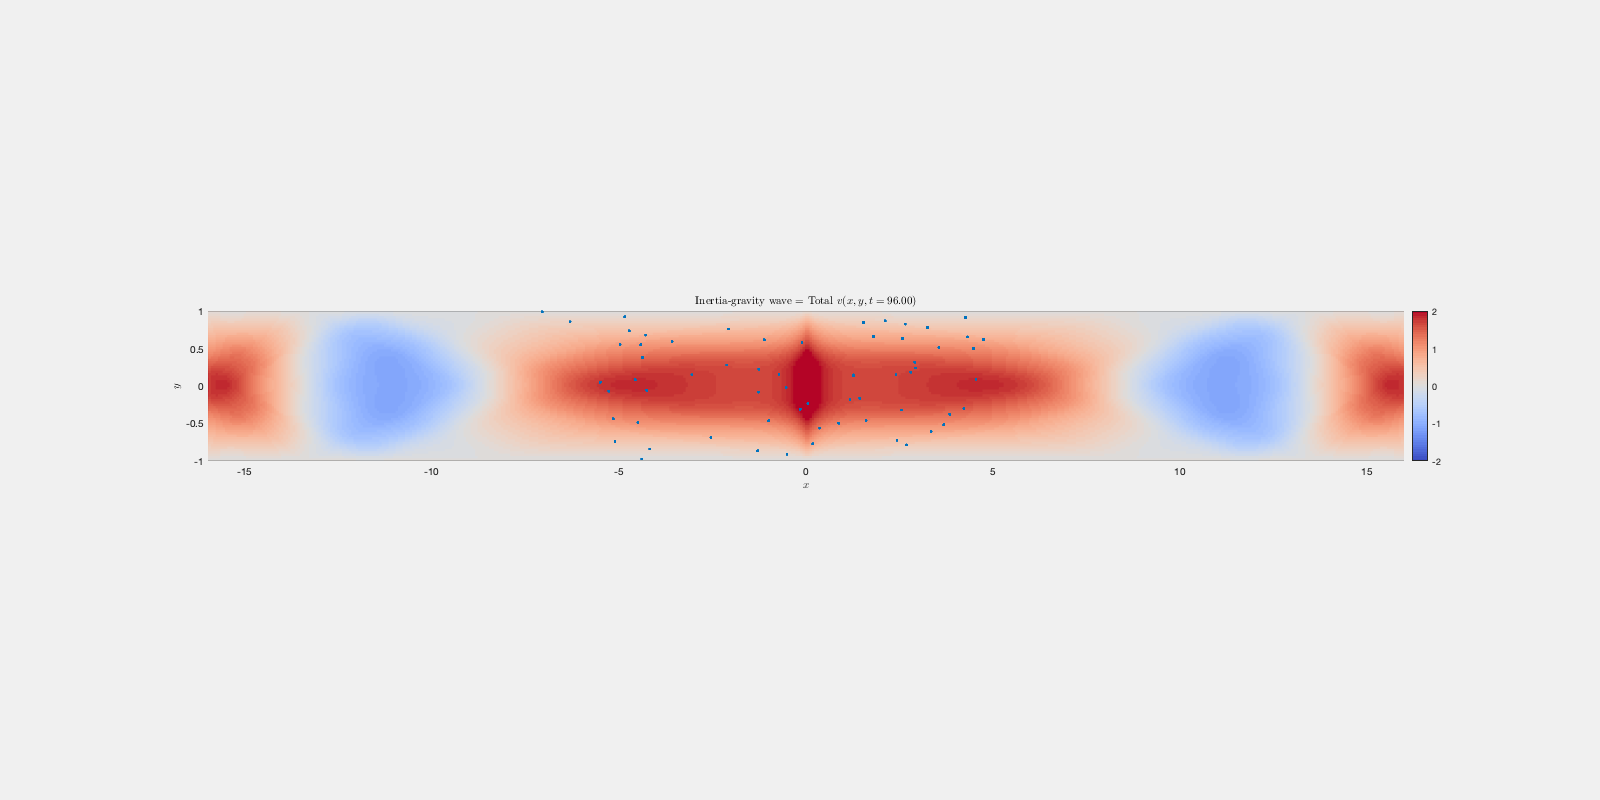



vidfiles{1} = VideoWriter('channel_v.mp4','MPEG-4');
open(vidfiles{1}) ;
figure(3)
set(gcf,'visible','on')
set(gcf,'Position', [800 200 1600 800]) ;
for tt = 1:numel(params.ts)
    subplot(3,1,2)
    pcolor(params.xs,params.ys,vH.total(:,:,tt)) ;
    tit_str = sprintf('Inertia-gravity wave = Total $v (x,y,t=%4.2f)$',params.ts(tt)) ;
    futz_plot(tit_str,params,part_x(tt,:))

    % Save frame
    F = getframe(gcf) ;
    writeVideo(vidfiles{1},F) ;
    hold off

end % tt

close(vidfiles{1})

fprintf(1,' Done in [%6.4f]s.\n\n',toc)

 Done in [7820.7501]s.



## Local functions

function params = define_params

% Parameters:
params.L_r            = 0.5 ;
params.M              = 2 ;
params.channel_length = 16*params.M ;           % Only show middle half in animations
params.f              = 1 ;
params.N              = 6 ;
params.Np             = 64 ;
params.Delta_eta      = 0.02 ;
NT                    = 256 ;
fprintf(1,' Channel length      = [%4.1f],\n',params.channel_length) ;
fprintf(1,' Channel width       = [%4.2f],\n',params.M) ;
fprintf(1,' Deformation radius  = [%4.2f],\n',params.L_r) ;

% Computed parameters:
params.n              = 2^params.N ;
params.ns             = 0:params.n ;
params.ms             = (2.*params.ns + 1).*pi/params.M ;
params.x              = linspace(-params.channel_length*params.M/2,params.channel_length*params.M/2,(params.channel_length/params.M)*params.n) ;
params.y              = linspace(-params.M/2,params.M/2,params.n) ;
[params.xs,params.ys] = ndgrid(params.x,params.y) ;
params.gH             = (params.L_r*params.f)^2 ;
t_f                   = 3*params.channel_length/(2*sqrt(params.gH)) ;     % Avoids periodic wraparound of IGWs
params.ts             = linspace(0,t_f,NT) ;
fprintf(1,' Gravity wave speed  = [%4.2f],\n\n',sqrt(params.gH)) ;
fprintf(1,' Grid resolution     = [%4.0d x%4.0d x%4.0d] [NX x NY x NT],\n',numel(params.x),numel(params.y),NT) ;
fprintf(1,' Number of particles = [%4.0d],\n',params.Np) ;
fprintf(1,' Delta_eta           = [%4.3f],\n',params.Delta_eta) ;

end

function [eta_KW,eta_IGW,u_KW,u_IGW] = compute_eta_u(t,params)
% t is a scalar time
% IGW part is antisymmetric wrt x so just compute positive x and then
% duplicate with sign flip.

root_gH  = sqrt(params.gH) ;
term1    = exp(-params.ys./params.L_r).*sign(params.xs - root_gH*t) ;
term2    = exp( params.ys./params.L_r).*sign(params.xs + root_gH*t) ;

eta_KW   = (term1 + term2)./(2*cosh(params.M/(2*params.L_r))) ;
  u_KW   = (term1 - term2)./(2*cosh(params.M/(2*params.L_r))) ;

inds     = find(params.x > 0) ;
pos_x    = params.x(inds) ;
eta_IGW  = zeros(size(pos_x,2),size(params.y,2)) ;
  u_IGW  = zeros(size(pos_x,2),size(params.y,2)) ;
for nn = 1:numel(params.ns)
    n             = params.ns(nn) ;
    m             = params.ms(nn) ;
    m_fac         = sqrt(1 + (m*params.L_r)^2) ;
    termm1        = 4.*((-1)^n)./(params.M.*m_fac^2) ;
    tmp0e         = termm1.*cos(m.*params.y)./m ;
    [~,eta_IGW1]  = ndgrid(pos_x,tmp0e) ;
    tmp0u         = termm1.*sin(m.*params.y).*params.L_r ;
    [~,  u_IGW1]  = ndgrid(pos_x,tmp0u) ;
    termm2        = 1 - exp(-m_fac.*pos_x./params.L_r) ;
    termm3        = (2/pi).*channel_IGW_integral1(m_fac,params.f*t,pos_x./params.L_r) ;
    [term2p3s,~]  = ndgrid(termm2' + termm3,params.y) ;
    eta_IGW       = eta_IGW + eta_IGW1.*term2p3s ;
      u_IGW       =   u_IGW +   u_IGW1.*term2p3s ;
end % nn
eta_IGW = [-flipud(eta_IGW); eta_IGW] ;
  u_IGW = [-flipud(  u_IGW);   u_IGW] ;

end

function v_IGW = compute_v(t,params)
% t is a scalar time
% v field is symmetric wrt x so just compute positive x and then duplicate

inds  = find(params.x > 0) ;
pos_x = params.x(inds) ;
v_IGW = zeros(size(pos_x,2),size(params.y,2)) ;
for nn = 1:numel(params.ns)
    n           = params.ns(nn) ;
    m           = params.ms(nn) ;
    m_fac       = sqrt(1 + (m*params.L_r)^2) ;
    tmp0        = 4.*((-1)^n).*cos(m.*params.y)./(m*params.M) ;
    [~,v_IGW1]  = ndgrid(pos_x,tmp0) ;
    tmp         = exp(-m_fac.*pos_x./params.L_r)./m_fac ;
    tmp2        = (2/pi).*channel_IGW_integral2(m_fac,params.f*t,pos_x./params.L_r) ;
    [term2p3,~] = ndgrid(tmp' - tmp2,params.y) ;
    v_IGW       = v_IGW + v_IGW1.*term2p3 ;
end % nn
v_IGW = [flipud(v_IGW); v_IGW] ;

end


Computes $\int_0 ^\infty k \sin k x \frac{\cos \sqrt{a^2 + k^2 }t}{a^2 + k^2} \; dk$ for many different $x>0$ values and a single $t$ and $a$. For $t < x$ an analytic solution exists.

function out = channel_IGW_integral1(a,t,x)

out        = zeros(size(x)) ;
inds1      = find(t <  x) ;
inds2      = find(t >= x) ;
out(inds1) = (pi/2).*exp(-a.*x(inds1)) ;
ks         = (2*pi).*linspace(0,1/min(x),numel(x)*4) ;
fac1       = a^2 + ks.^2 ;
[xx,kks]   = ndgrid(x(inds2),ks) ;

tmp_int    = kks.*sin(kks.*xx).*cos(sqrt(fac1).*t)./fac1 ;
tmp_int    = sum(tmp_int,2) ;
out(inds2) = tmp_int ;
out        = out' ;

end


Computes $\int_0 ^\infty \cos k x \frac{\cos \sqrt{a^2 + k^2 }t}{a^2 + k^2} \; dk$ for many different $x>0$ values and a single $t$ and $a$. For $t < x$ an analytic solution exists.

function out = channel_IGW_integral2(a,t,x)

out        = zeros(size(x)) ;
inds1      = find(t <  x) ;
inds2      = find(t >= x) ;
out(inds1) = (pi/(2*a)).*exp(-a.*x(inds1)) ;
ks         = (2*pi).*linspace(0,1/min(x),numel(x)*4) ;
fac1       = a^2 + ks.^2 ;
[xx,kks]   = ndgrid(x(inds2),ks) ;

tmp_int    = cos(kks.*xx).*cos(sqrt(fac1).*t)./fac1 ;
tmp_int    = sum(tmp_int,2) ;
out(inds2) = tmp_int ;
out        = out' ;

end

function futz_plot(tit_str,params,part_x)

shading flat ;
colorbar
xlim((params.channel_length/2).*[-1 1]) ;
pbaspect([params.channel_length/2 params.M 1])
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
title(tit_str,'Interpreter','latex')
caxis(2.*[-1 1]) ;
set(gca,'Box','on') ;
c_map = diverging_map(linspace(0,1,64),[0.230, 0.299, 0.754],[0.706, 0.016, 0.150]) ;
colormap(c_map) ;
drawnow

% Particles
hold on
plot(part_x(1:params.Np),part_x(params.Np+1:end),'.') ;

end

function d_part_xdt = rhs_particle(t,part_x,uInterp,vInterp)

Np         = numel(part_x)/2 ;
tvec       = t.*ones(Np,1) ;
u          = uInterp(part_x(1:Np),part_x(Np+1:end),tvec) ;
v          = vInterp(part_x(1:Np),part_x(Np+1:end),tvec) ;
d_part_xdt = [u; v] ;

end